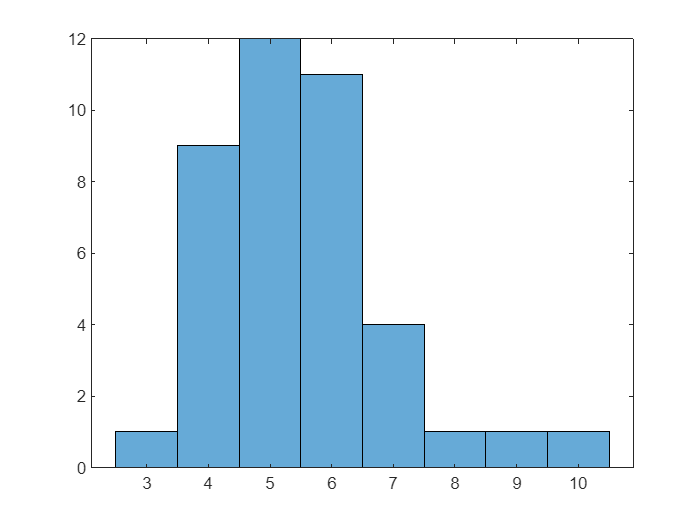

ans = 220

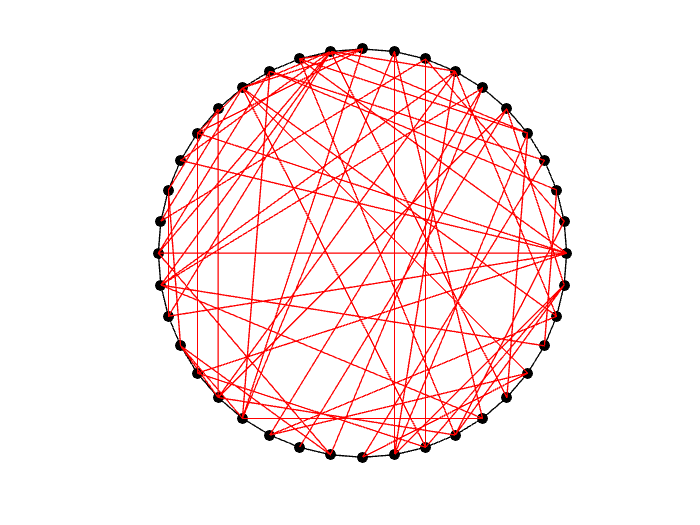

% NWnetwork_compressed_twoway(N,m,p,type_of_neuron)
% N 网络节点数
% m 连接度
% p 每个节点与其他N-m个节点的连接概率
% type_of_neuron 每个节点的类型
% 该函数生成压缩矩阵形式的连接矩阵，并绘制网络
% 双向连接的特性并不体现在网络连接图中
clear
clc

% 示例
N = 40;
m = 1;
p = 0.1;
type_of_neuron = ones(N,1);
% type_of_neuron(1:N/2) = 2;
% [ConnectMatrix1]= NWnetwork_compressed_twoway_banben2(N,m,p,type_of_neuron); 
[ConnectMatrix1]= NWnetwork_compressed_twoway_banben2(N,m,p,type_of_neuron); 

## 对比，WattsStrogatz小世界网络

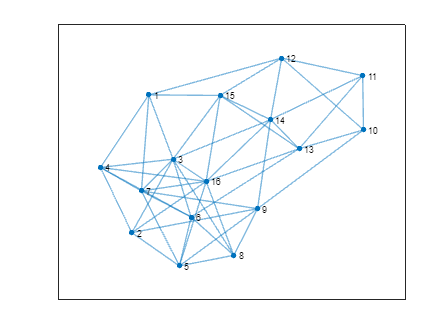

N    = 16;
K    = 3;
beta = 0.4;
h = WattsStrogatz(N,K,beta);
figure; plot(h);

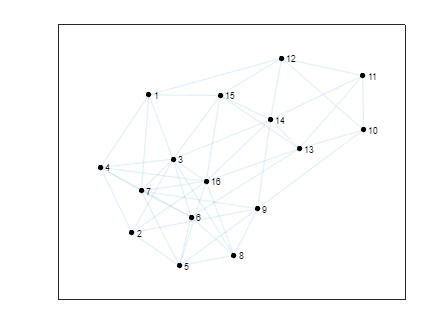

plot(h,'NodeColor','k','EdgeAlpha',0.1); 

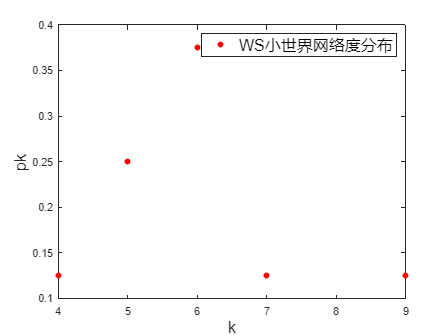

% ConnectMatrix = table2array(h.Edges);
% ConnectMatrix_reciprocal = [ConnectMatrix(:,2) ConnectMatrix(:,1)];
% ConnectMatrix = [ConnectMatrix;ConnectMatrix_reciprocal];
% connectType   = 22.*ones(2*N*K,1);
% ConnectMatrix = [ConnectMatrix connectType]; 

[kh,pkh] = my_degree(h);
% plot(kh,pkh,'ro','MarkerSize',5,'MarkerFaceColor','r')
histograpm()
xlabel('k','FontSize',15)
ylabel('pk','FontSize',15)
legend('WS小世界网络度分布','FontSize',15)

## 根据ConnectMatrix计算度分布

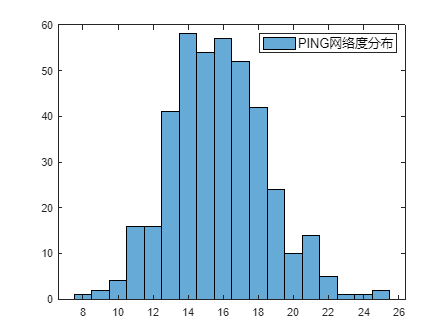

cd('F:\MATLAB Works\Abstract network');
% load('inital_simulation_INGpacingIEnetwork3.mat')
load('inital_simulation_smallING.mat')

Connect_num = zeros(n,1);
for i = 1:n
    Connect_num(i,1) = length(find(ConnectMatrix(:,1)==i));
end

figure;
histogram(Connect_num);
legend('PING网络度分布','FontSize',12)

## 从graph格式计算度分布

function [k,pk] = my_degree(G)
    N   = numnodes(G);
    k   = [];
    pk  = [];
    deg = degree(G); 
    unique_deg = unique(deg);

    for i = 1:length(unique_deg)
        count_k = 0;
        for j = 1:length(deg)
            if unique_deg(i) == deg(j); 
                count_k = count_k + 1;
            end
        end

        k(i)  = unique_deg(i);
        pk(i) = count_k;
    end

    pk = pk/N; 

    for i = 1:length(k)
        if (k(i)==0) || (pk(i)==0)
            k(i)  = [];
            pk(i) = [];
        end
    end
end